# Stock Data - Outlier Removal

Extremely volatile stocks can be troublesome for certain calculations. For this exercise, we will remove any stocks with one or more daily returns outside the range [-1, 1].

## 1. 

Load data from `stockData_allCapSizes.mat`.

load stockData_allCapSizes.mat

## 2. 

Extract the stock data from `stockPrices`into a matrix called `prices`. Calculate the returns using the following command: 

`logReturns = diff(log(prices))`

prices = stockPrices{:, 2:end};
rets = diff(log(prices))

rets =     0.0480   -0.0345    0.0142    0.0800   -0.0131   -0.0122    0.0257   -0.0489   -0.0191   -0.0159   -0.0014    0.0059         0   -0.0299   -0.0474   -0.0283    0.0051   -0.0426   -0.0277   -0.0549   -0.0081   -0.0330    0.0156   -0.0103   -0.0046   -0.0082   -0.0199   -0.0032    0.0049   -0.0038    0.0285   -0.0174         0         0   -0.0042   -0.0237    0.0037   -0.0114   -0.0180   -0.0081   -0.0051    0.0123   -0.0156   -0.0044    0.0054   -0.0023   -0.0181   -0.0311   -0.0053   -0.0186
   -0.0317    0.0169    0.0145    0.4308    0.0111    0.0218   -0.0039   -0.0186    0.0085   -0.0078    0.0014   -0.0267   -0.0328    0.0588   -0.0077    0.0112    0.0249   -0.0044    0.0251    0.0056    0.0014    0.0087   -0.0196   -0.0058   -0.0185    0.0082    0.0248   -0.0089   -0.0136   -0.0082   -0.0103    0.0002    0.0180   -0.0114    0.0188   -0.0172   -0.0046    0.0040    0.0012    0.0062    0.0019   -0.0103   -0.0097    0.0044    0.0798         0   -0.0008   -0.0238   -0.0107  

## 3. 

Create a logical variable to identify which stocks have at least one **absolute **return greater than 1 (i.e., contain an outlier). What are the names of these stocks?

stockHasOutlier = any(abs(rets) > 1);
% Which stocks have outliers?
stockInfo.StockName(stockHasOutlier)

ans = 5×1 cell array
    {'Equal Energy Ltd. Common Shares'}
    {'Acorda Therapeutics, Inc.'      }
    {'Dendreon Corporation'           }
    {'Human Genome Sciences, Inc.'    }
    {'InterMune, Inc.'                }

## 4. 

Remove any stocks that contain an outlier from the `stockInfo`table, the `stockPrices`table, and the matrix of returns calculated in step 2.

newPrices = stockPrices(:, [true, ~stockHasOutlier]);
newStockInfo = stockInfo(~stockHasOutlier, :)

newStockInfo = 117×4 table
                        StockName                          StockSector               MarketCap    CapSize
            _________________________________    ________________________________    _________    _______
    BPZ     'BPZ Resources, Inc Common Stock'    Oil & Gas Drilling & Exploration     0.55078      Small 
    BRNC    'Bronco Drilling Company, Inc.'      Oil & Gas Drilling & Exploration     0.31623      Small 
    LNG     'Cheniere Energy, Inc. Common St'    Oil & Gas Drilling & Exploration     0.60685      Small 
    NEP     'China North East Petroleum Hold'    Oil & Gas Drilling & Exploration     0.12641      Small 
    CRT     'Cross Timbers Royalty Trust Com'    Oil & Gas Drilling & Exploration     0.27378      Small 
    

rets = rets(:, ~stockHasOutlier)

rets =     0.0480   -0.0345    0.0142    0.0800   -0.0131    0.0257   -0.0489   -0.0191   -0.0159   -0.0014    0.0059         0   -0.0299   -0.0474   -0.0283    0.0051   -0.0426   -0.0277   -0.0549   -0.0081   -0.0330    0.0156   -0.0103   -0.0046   -0.0082   -0.0199   -0.0032    0.0049   -0.0038    0.0285   -0.0174         0         0   -0.0042   -0.0237    0.0037   -0.0114   -0.0180   -0.0081   -0.0051    0.0123   -0.0156   -0.0044    0.0054   -0.0023   -0.0181   -0.0311   -0.0053   -0.0186   -0.0250
   -0.0317    0.0169    0.0145    0.4308    0.0111   -0.0039   -0.0186    0.0085   -0.0078    0.0014   -0.0267   -0.0328    0.0588   -0.0077    0.0112    0.0249   -0.0044    0.0251    0.0056    0.0014    0.0087   -0.0196   -0.0058   -0.0185    0.0082    0.0248   -0.0089   -0.0136   -0.0082   -0.0103    0.0002    0.0180   -0.0114    0.0188   -0.0172   -0.0046    0.0040    0.0012    0.0062    0.0019   -0.0103   -0.0097    0.0044    0.0798         0   -0.0008   -0.0238   -0.0107   -0.0307  

## 5. 

Separate the returns by `CapSize` and create histograms of the outlier-free returns for small-, mid- and large-cap stocks on three subplots.

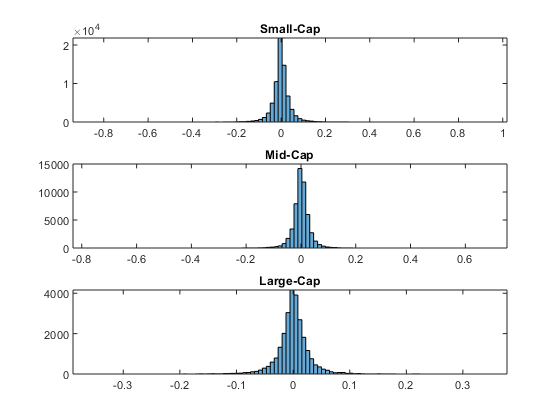

capsize = categories(stockInfo.CapSize);
n = numel(capsize);
figure
for k = 1:n
    capRets = rets(:, newStockInfo.CapSize == capsize(k));
    subplot(n,1,k)
    histogram(capRets, 100)
    title([capsize{k}, '-Cap'])
end